clc; clear all; close all;

% function [t,P] = Experimento(Kcat,KM,Kp,Cn)

Kcat = 10;
KM = 1e3;
Kp = 1e-9;
Cn = 10;

% Calcula la producción en una simulación de experimento

%% INPUTS %%

%% OUTPUTS %%

%% PROCESO %%

% Parámetros

Kd = 1e-4;
K1 = 10;
K_1 = 1e-2;
n = 2;
I = 1e-2;
Kleak = 1e-12;
Kdeg = 1e-6;
PrT = 1;

% Integración + Detección de evento

y0 = [1000; PrT; 0; 0];
tf = 100000000;
options = odeset('Events', @(t,y)FinalReact_Event(t,y,Kcat,KM,Kp,Cn,Kd,K1,K_1,n,I,Kleak,Kdeg,PrT));

[t,y,te,ye,ie] = ode15s(@(t,y)odefun(t,y,Kcat,KM,Kp,Cn,Kd,K1,K_1,n,I,Kleak,Kdeg,PrT),[0, tf],y0, options);
test = odefun(te,ye,Kcat,KM,Kp,Cn,Kd,K1,K_1,n,I,Kleak,Kdeg,PrT);

Index exceeds the number of array elements (0).

Error in live>odefun (line 145)
        if y(i)<0


% PLOT

figure 

% Sustrato

subplot(2,2,1)
plot(t,y(:,1),'b', 'LineWidth', 2)
title('Sustrato')
xlabel('t(s)','Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel('$S(\mu Mol)$','Interpreter','latex','FontWeight','bold','FontSize',14)
grid on

% Promotor Activado

subplot(2,2,2)
plot(t,y(:,2),'r', 'LineWidth', 2)
title('Prom. Activo')
xlabel('t(s)','Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel('$P_{r}^{*}(\mu Mol)$','Interpreter','latex','FontWeight','bold','FontSize',14)
grid on

% Enzima

subplot(2,2,3)
plot(t,y(:,3),'g', 'LineWidth', 2)
title('Enzimas')
xlabel('t(s)','Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel('$E_{T}(\mu Mol)$','Interpreter','latex','FontWeight','bold','FontSize',14)
grid on

% Producto

subplot(2,2,4)
plot(t,y(:,4),'m', 'LineWidth', 2)
title('Producto')
xlabel('t(s)','Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel('$P(\mu Mol)$','Interpreter','latex','FontWeight','bold','FontSize',14)
grid on


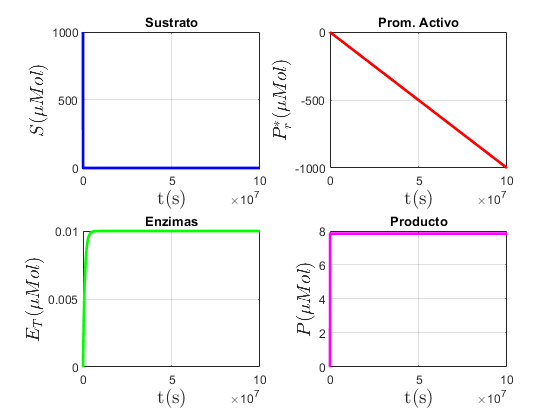

figure 

% Sustrato

subplot(2,2,1)
plot(t,y(:,1),'b', 'LineWidth', 2)
title('Sustrato')
xlabel('t(s)','Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel('$S(\mu Mol)$','Interpreter','latex','FontWeight','bold','FontSize',14)
grid on

% Promotor Activado

subplot(2,2,2)
plot(t,y(:,2),'r', 'LineWidth', 2)
title('Prom. Activo')
xlabel('t(s)','Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel('$P_{r}^{*}(\mu Mol)$','Interpreter','latex','FontWeight','bold','FontSize',14)
grid on

% Enzima

subplot(2,2,3)
plot(t,y(:,3),'g', 'LineWidth', 2)
title('Enzimas')
xlabel('t(s)','Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel('$E_{T}(\mu Mol)$','Interpreter','latex','FontWeight','bold','FontSize',14)
grid on

% Producto

subplot(2,2,4)
plot(t,y(:,4),'m', 'LineWidth', 2)
title('Producto')
xlabel('t(s)','Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel('$P(\mu Mol)$','Interpreter','latex','FontWeight','bold','FontSize',14)
grid on

function [value,isterminal,direction] = FinalReact_Event(t,y,Kcat,KM,Kp,Cn,Kd,K1,K_1,n,I,Kleak,Kdeg,PrT)

    epsilon = 1e-7;
    Dy_Dt = odefun(t,y,Kcat,KM,Kp,Cn,Kd,K1,K_1,n,I,Kleak,Kdeg,PrT);
    n_Dy_Dt = norm(Dy_Dt,2);
    
    if n_Dy_Dt < epsilon
        
        value = 0;
        
    else
        
        value = 1;
        
    end
    
    isterminal = 1;
    direction = 0;

end


function dydt = odefun(t,y,Kcat,KM,Kp,Cn,Kd,K1,K_1,n,I,Kleak,Kdeg,PrT)

    dydt = zeros(4,1);
    
    for i = 1:4
        
        if y(i)<0
            
            y(i) = 0;
            
        end
    end
    
    dydt(1) = - Kd*y(1) - ((Kcat*y(3)*y(1))/(KM + y(1)));  % Sustrato
    dydt(2) = -(K1*(I^n)/(100 + I^n) + (K_1*y(2)));   % Promotor inactivado
    dydt(3) = Kleak*y(2) + Cn*Kp*(PrT - y(2)) - (Kdeg*y(3));  % Encima Total
    dydt(4) = ((Kcat*y(3)*y(1))/(KM + y(1)));    % Producto

    
    % ALTERNATIVA HILL: 
%     dydt(2) = K1*(I^n)/(K_0 + I^n) - (K_1*y(2));   % Promotor Activado
    % ALTERNATIVA, promotor inactivado:
 
      
end
